**面积高程积分（HI, Hypsometric Integral）**

根据Strahler（1952）的侵蚀地形学，高程积分（HI ）能够揭示流域在发育过程中，其地表侵蚀与隆升之间的关系，HI值计算公式为：


$$\textrm{HI}=\frac{H_{\textrm{avg}} -H_{\min } }{H_{\max } -H_{\min } }$$


其中，$H_{\min }$表示流域的最低点高程，$H_{\max }$代表流域的最高点高程值，$H_{\textrm{avg}}$则是流域的平均高程值。

一般来说，HI 值总是介于 0 和 1 之间。HI值越大，便表明该地貌经历强烈的构造变形阶段，处于地貌发育初始阶段；反之HI值越小，表示现今地貌经历构造变形弱或者未经历构造变形，处于地貌发育晚期阶段。

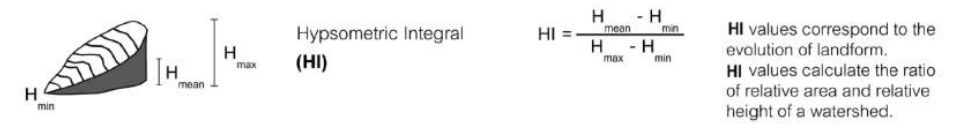

function HI_index = ttb_calculate_hi_index(dem)
    % 提取有效的高程值
    valid_elevation = dem.Z(~isnan(dem.Z));

    % 计算 H_max
    max_elevation = max(valid_elevation);

    % 计算 H_min
    min_elevation = min(valid_elevation);

    % 计算 H_avg
    mean_elevation = mean(valid_elevation);

    % 代入公式计算得到 HI 值
    HI_index = (mean_elevation - min_elevation) / (max_elevation - min_elevation);
end

参考文献：